# Stability Analysis

## Parameters Initializatio


M = 1; 
m = 0.5;
l = 0.5;
g = 9.81;


## A, B, C D Matrix


% x_dot = Ax + Bu
A = [0, 1, 0, 0; 0, 0, -g*m/M, 0; 0, 0, 0, 1; 0, 0, -g*(M+m)/(M*l), 0];
B = [0; 1/M; 0; 1/(M*l)];
C = [0, 1, 0, 0; 0, 0, 0, 1];
D = 0;
A

A =          0    1.0000         0         0
         0         0   -4.9050         0
         0         0         0    1.0000
         0         0  -29.4300         0


B

B =      0
     1
     0
     2


## Check internal stability

eig(A)

ans =    0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 5.4249i
   0.0000 - 5.4249i


## Check Controllability

Co = ctrb(A, B);
rank(Co)

ans = 4

## Check Observability

Ob = obsv(A, C);
rank(Ob)

ans = 3

## Pole-Zero Map

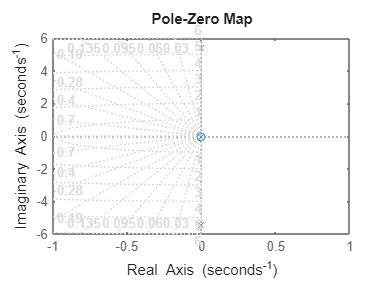

sys = ss(A, B, C, D);
pzmap(sys)
grid on

sys


sys =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2       0       0  -4.905       0
   x3       0       0       0       1
   x4       0       0  -29.43       0
 
  B = 
       u1
   x1   0
   x2   1
   x3   0
   x4   2
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
   y2   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.


## Time-Domain Response (Impulse or Step)

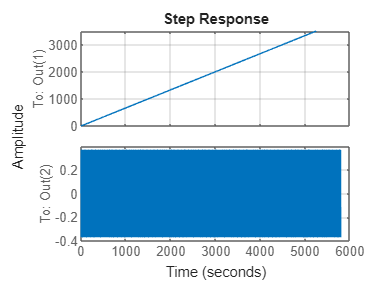

step(sys)   % or impulse(sys)
grid on

## Impulse Response

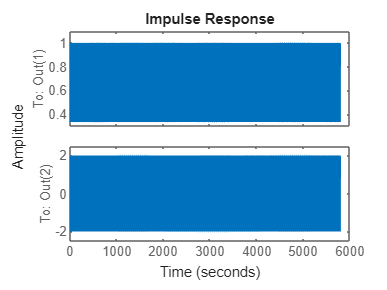

impulse(sys)